# Laboratory 9


$${H_f }_1 =\frac{2\ldotp 4}{\left(0\ldotp 5s+1\right)\left(50s+1\right)}$$


We use the next approximation to simplify the transfer functionn:


$$\left(T_1 s+1\right)\left(T_2 s+1\right)=\left(T_1 +T_2 \right)s+1$$



$${H_f }_1 =\frac{2\ldotp 4}{50\ldotp 5s+1}$$



$${H_f }_2 =\frac{8\ldotp 6}{\left(0\ldotp 0\textrm{1s}+1\right)\left(0\ldotp 6s+1\right)}$$


Hf1 = tf(2.4,[50.5 1]);
Hf2 = tf(8.6,[0.6 1])*tf(1,[0.01 1]);
Tsigma = 0.5;
Ho2 = tf(1,[2*Tsigma^2 2*Tsigma 0]);
Hr2 = Ho2/Hf2;
zpk(Hr2)

ans =
 
  0.0013953 (s+100) (s+1.667)
  ---------------------------
            s (s+2)
 
Continuous-time zero/pole/gain model.



Ho1 = tf([4*Tsigma 1],[8*Tsigma^3 8*Tsigma^2 0 0]);
Hr1 = Ho1/Hf1/Ho2;
zpk(Hr1)

ans =
 
  21.042 s (s+2) (s+0.5) (s+0.0198)
  ---------------------------------
              s^2 (s+2)
 
Continuous-time zero/pole/gain model.



We can use the previous approximation to simplify ${H_r }_1$

(s+2)(s+0.0198) = 2*0.0198*(1/2*s+1)(1/0.0198*s+1) = 2*0.0198*((1/2+1/0.0198)s+1) = (2+0.0198)*s+2*0.0198 = 2.0198*s+0.0396

Hr1f = 21.042*tf([1 0.5],[1 0])*tf([2.0198 0.0396],[1 2]);
zpk(Hr1f)

ans =
 
  42.501 (s+0.5) (s+0.01961)
  --------------------------
           s (s+2)
 
Continuous-time zero/pole/gain model.



Ho = tf([4*Tsigma 1],[8*Tsigma^3 8*Tsigma^2 0 0]);
Hr = Ho/Hf1/Hf2;
zpk(Hr)

ans =
 
  0.02936 (s+100) (s+1.667) (s+0.5) (s+0.0198)
  --------------------------------------------
                   s^2 (s+2)
 
Continuous-time zero/pole/gain model.



We can use the previous approximation to simplify Hr:

(s+100)(s+0.0198) = 100*0.0198*(1/100*s+1)(1/0.0198*s+1) = 100*0.0198*((1/100+1/0.0198)s+1) = (100+0.0198)*s+100*0.0198 = 100.0198*s+1.98

Hrf = 0.02936*tf([1 1.667],[1 0])*tf([1 0.5],[1 0])*tf([100.0198 1.98],[1 2]);
zpk(Hrf)

ans =
 
  2.9366 (s+1.667) (s+0.5) (s+0.0198)
  -----------------------------------
               s^2 (s+2)
 
Continuous-time zero/pole/gain model.



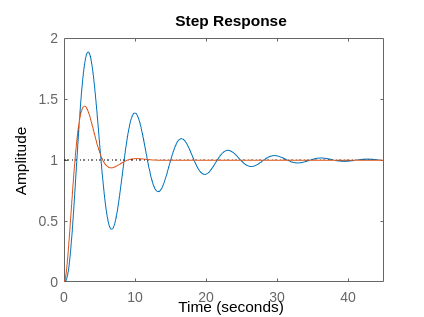

figure;
hold on;
step(feedback(Hr1f*Hf1*Ho2,1));
step(feedback(Hrf*Hf1*Hf2,1));
hold off;